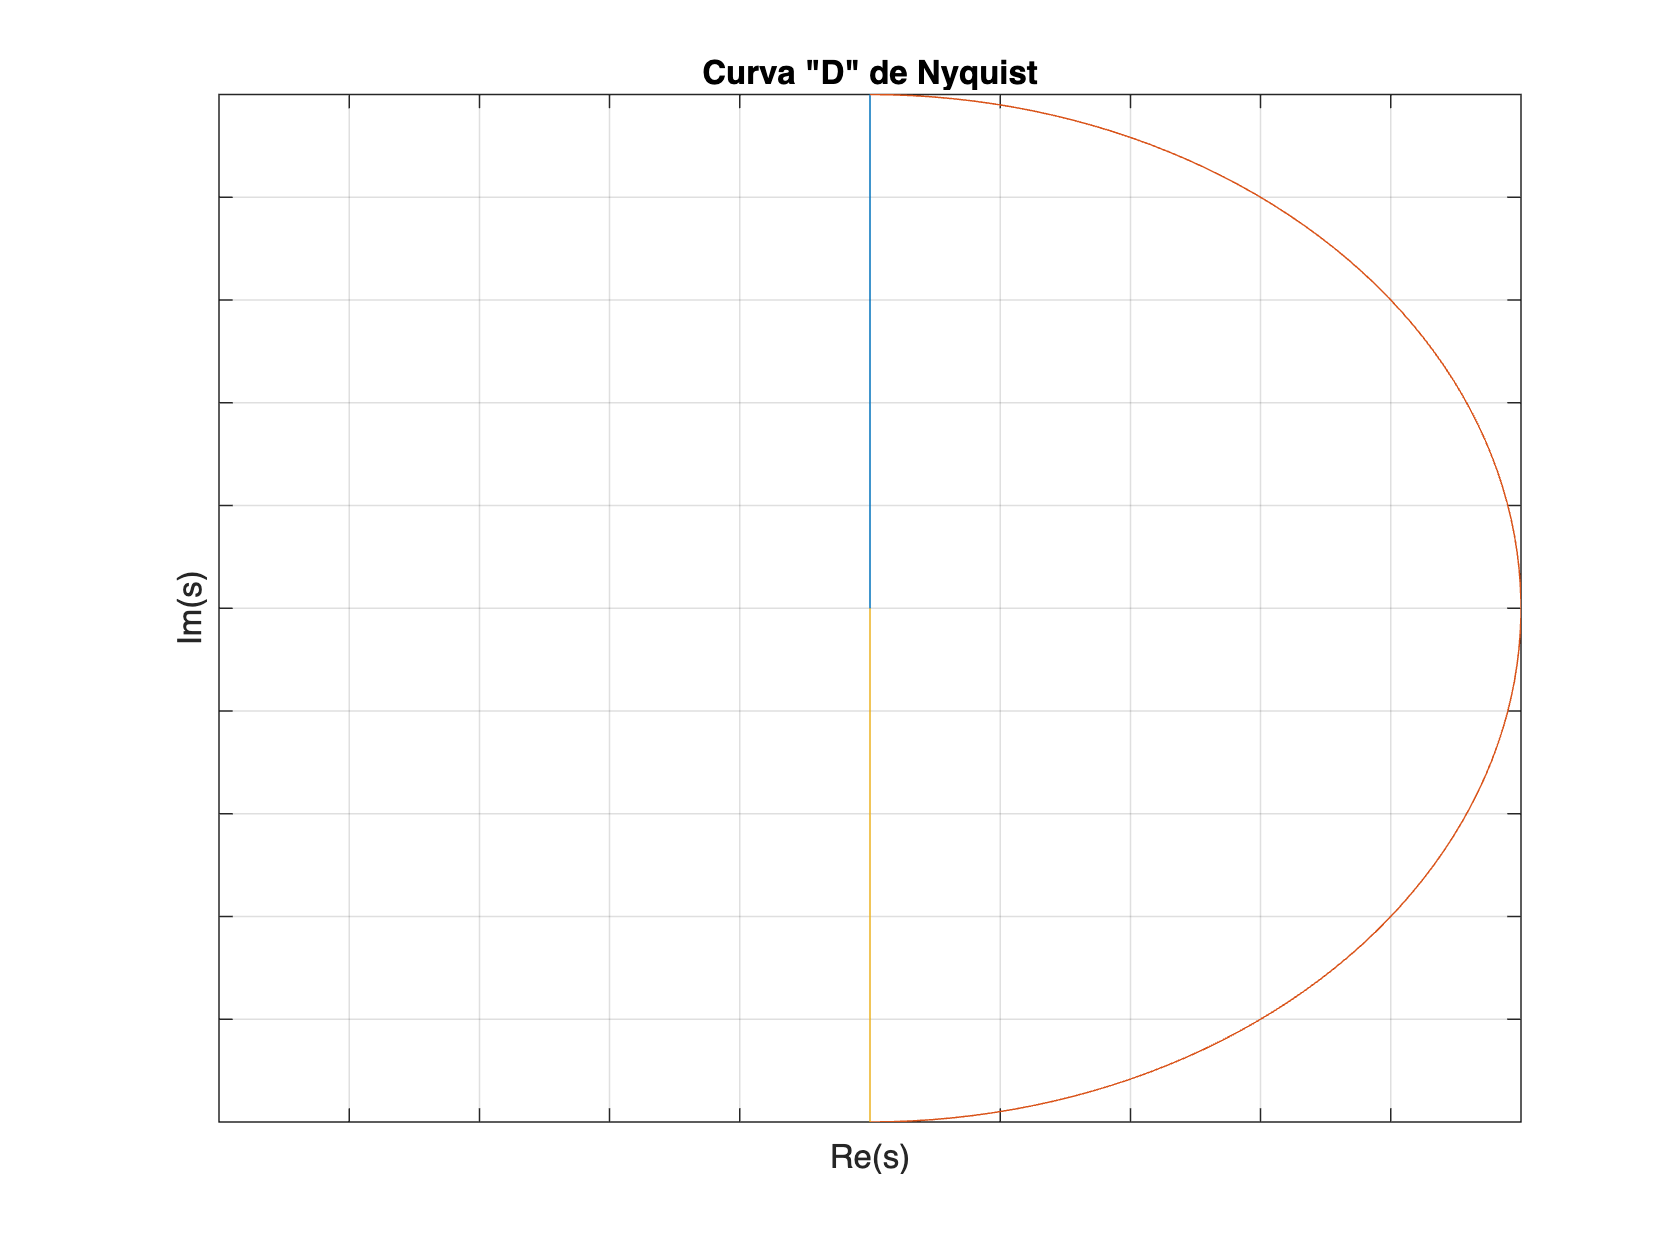

Nmax = 3;
w_vec = logspace(-3,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
s1 = 1i*w_vec; % eixo imaginario positivo
s2 = R*exp(1i*theta_vec); % semi-circunferencia de raio "muito grande"
s3 = -s1; % eixo imaginario negativo
figure();
plot([s1]); hold all; plot(s2); plot(s3); axis([-10^Nmax 10^Nmax -10^Nmax 10^Nmax]); 
grid on; title('Curva "D" de Nyquist'); xlabel('Re(s)'); ylabel('Im(s)');
set(gca,'XTickLabel',[], 'YTickLabel', [])


$$G(s) = \frac{1}{s+1}$$


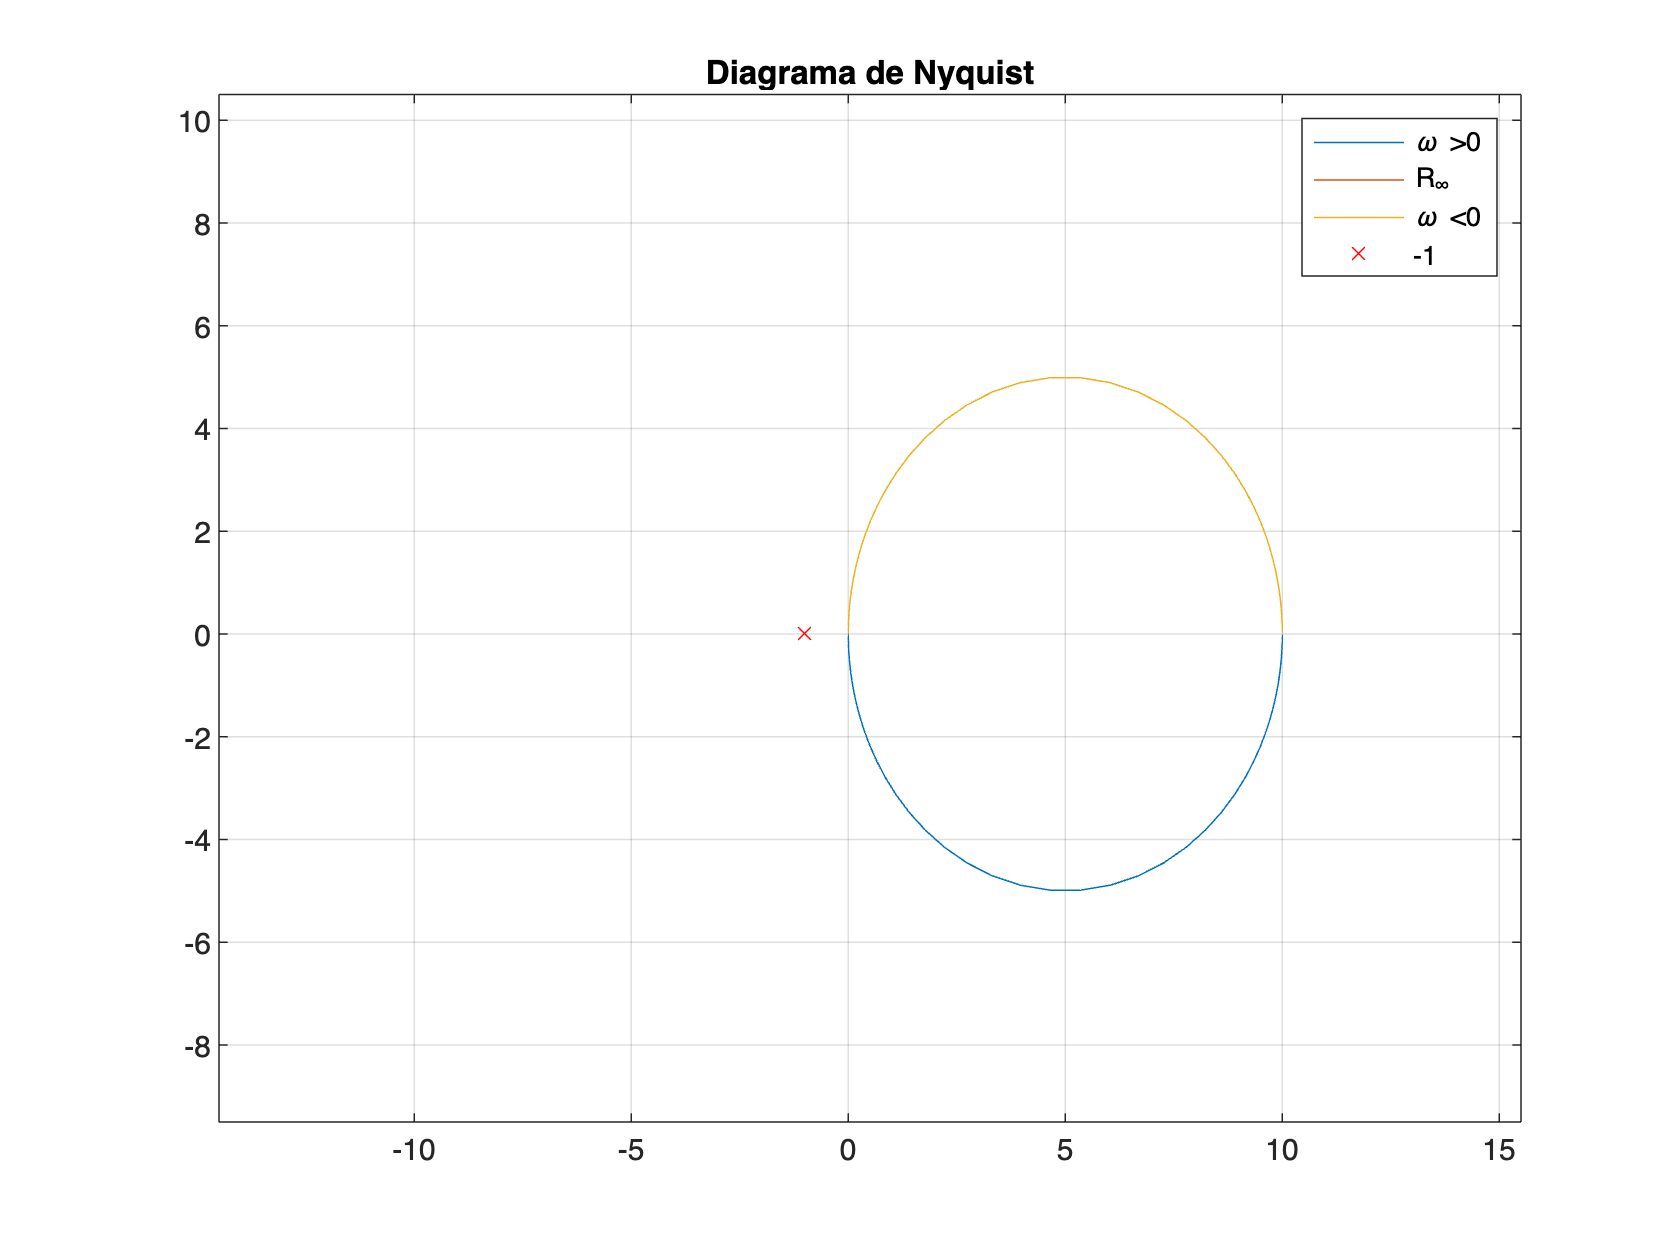

a = 1;
G = @(s) 10./((s+a));
figure();
plot(G([s1])); hold all;title('Diagrama de Nyquist')
plot(G((s2))); plot(G(-flip(s1))); 
plot([-1+0.00000000001i], 'xr'); axis([-1.5 1.5 -1 1]*10)
legend('\omega >0 ', 'R_\infty', '\omega <0', '-1'); grid on;

xlim([-14.5 15.5])
ylim([-9.5 10.5])

E se existirem polos no eixo imaginário?

Nmax = 3;
Nmin = -2

Nmin = -2

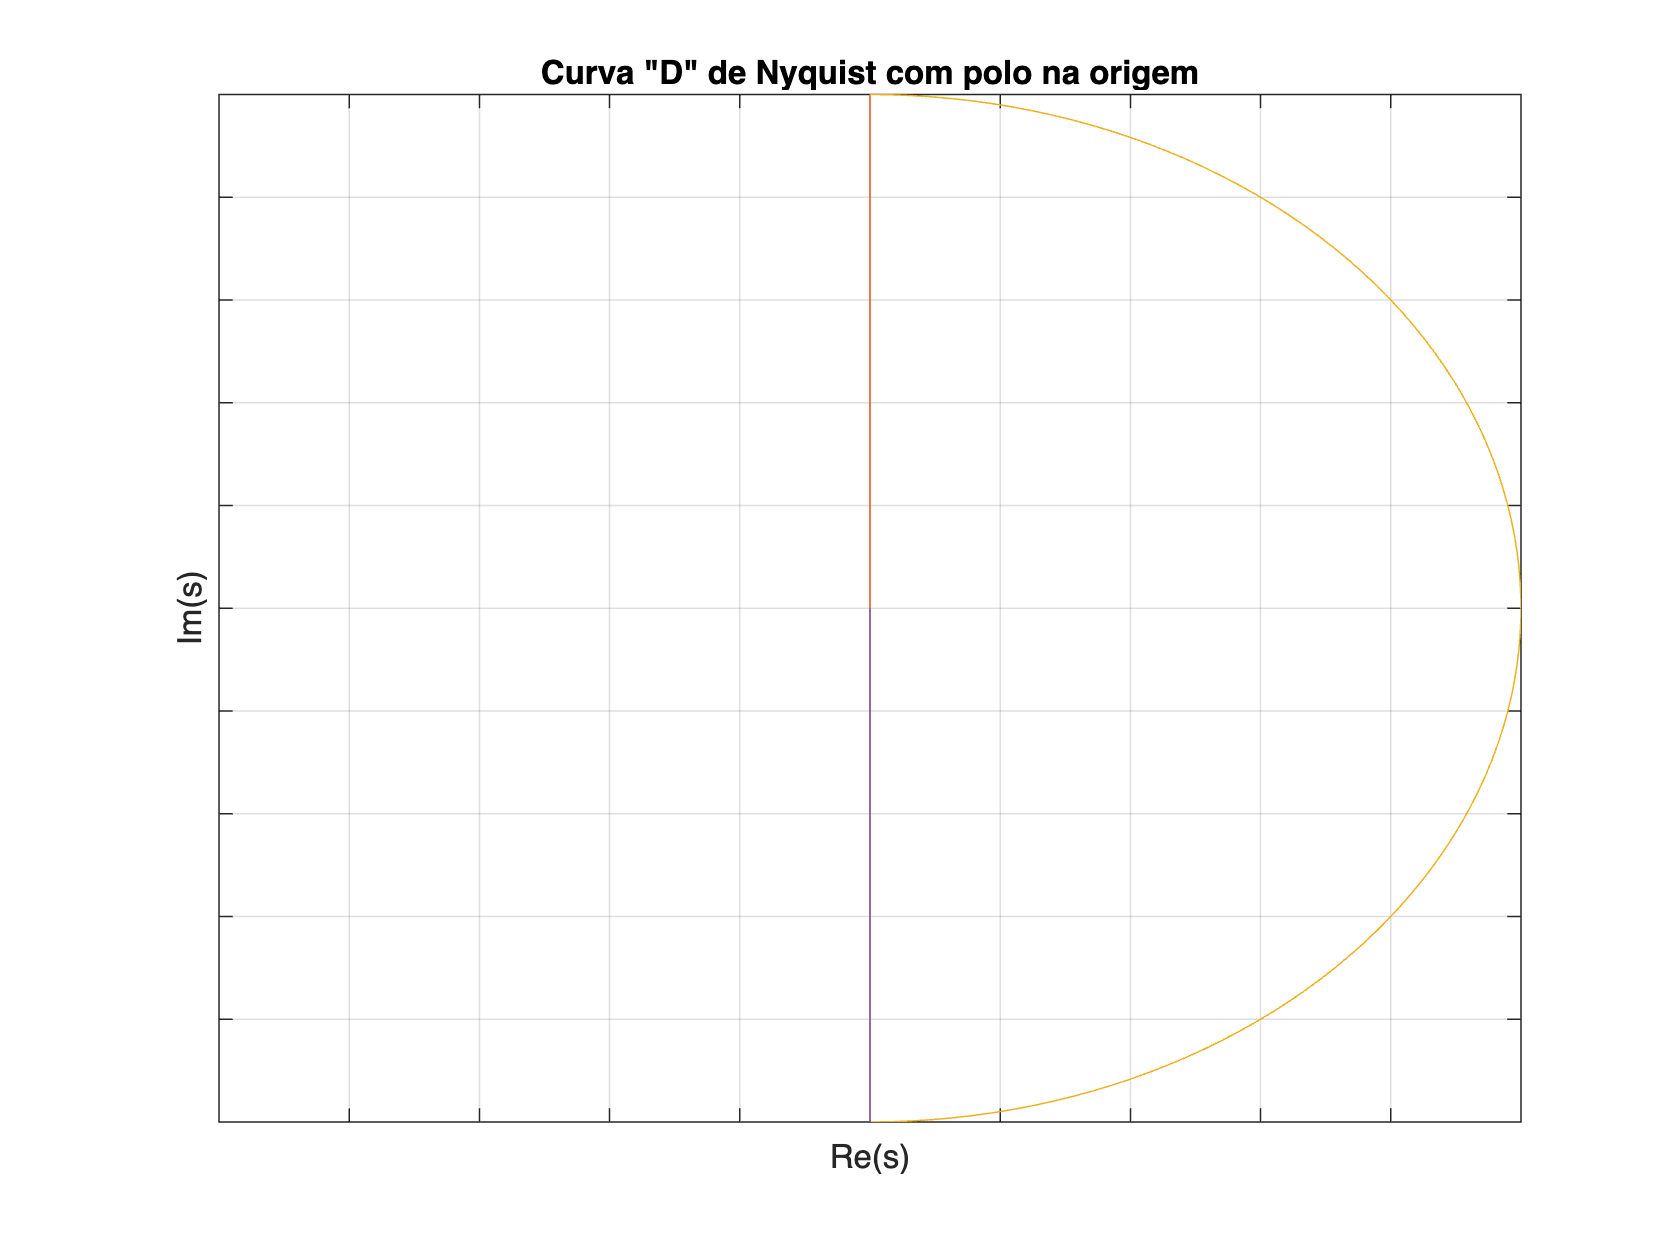

w_vec = logspace(Nmin,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
Rpequeno = 10^Nmin;
s0 = Rpequeno*flip(exp(1i*theta_vec)); % raio pequeno em torno da origem
s1 = 1i*w_vec; % eixo imaginario
s2 = R*exp(1i*theta_vec); % raio grande / infinito
figure();
plot(s0);hold all;plot(s1);plot(s2);plot(-s1);
axis([-10^Nmax 10^Nmax -10^Nmax 10^Nmax]); 
grid on; title('Curva "D" de Nyquist com polo na origem'); xlabel('Re(s)'); ylabel('Im(s)');
set(gca,'XTickLabel',[], 'YTickLabel', []);
set(gca,'XTickLabel',[], 'YTickLabel', []);

exemplo

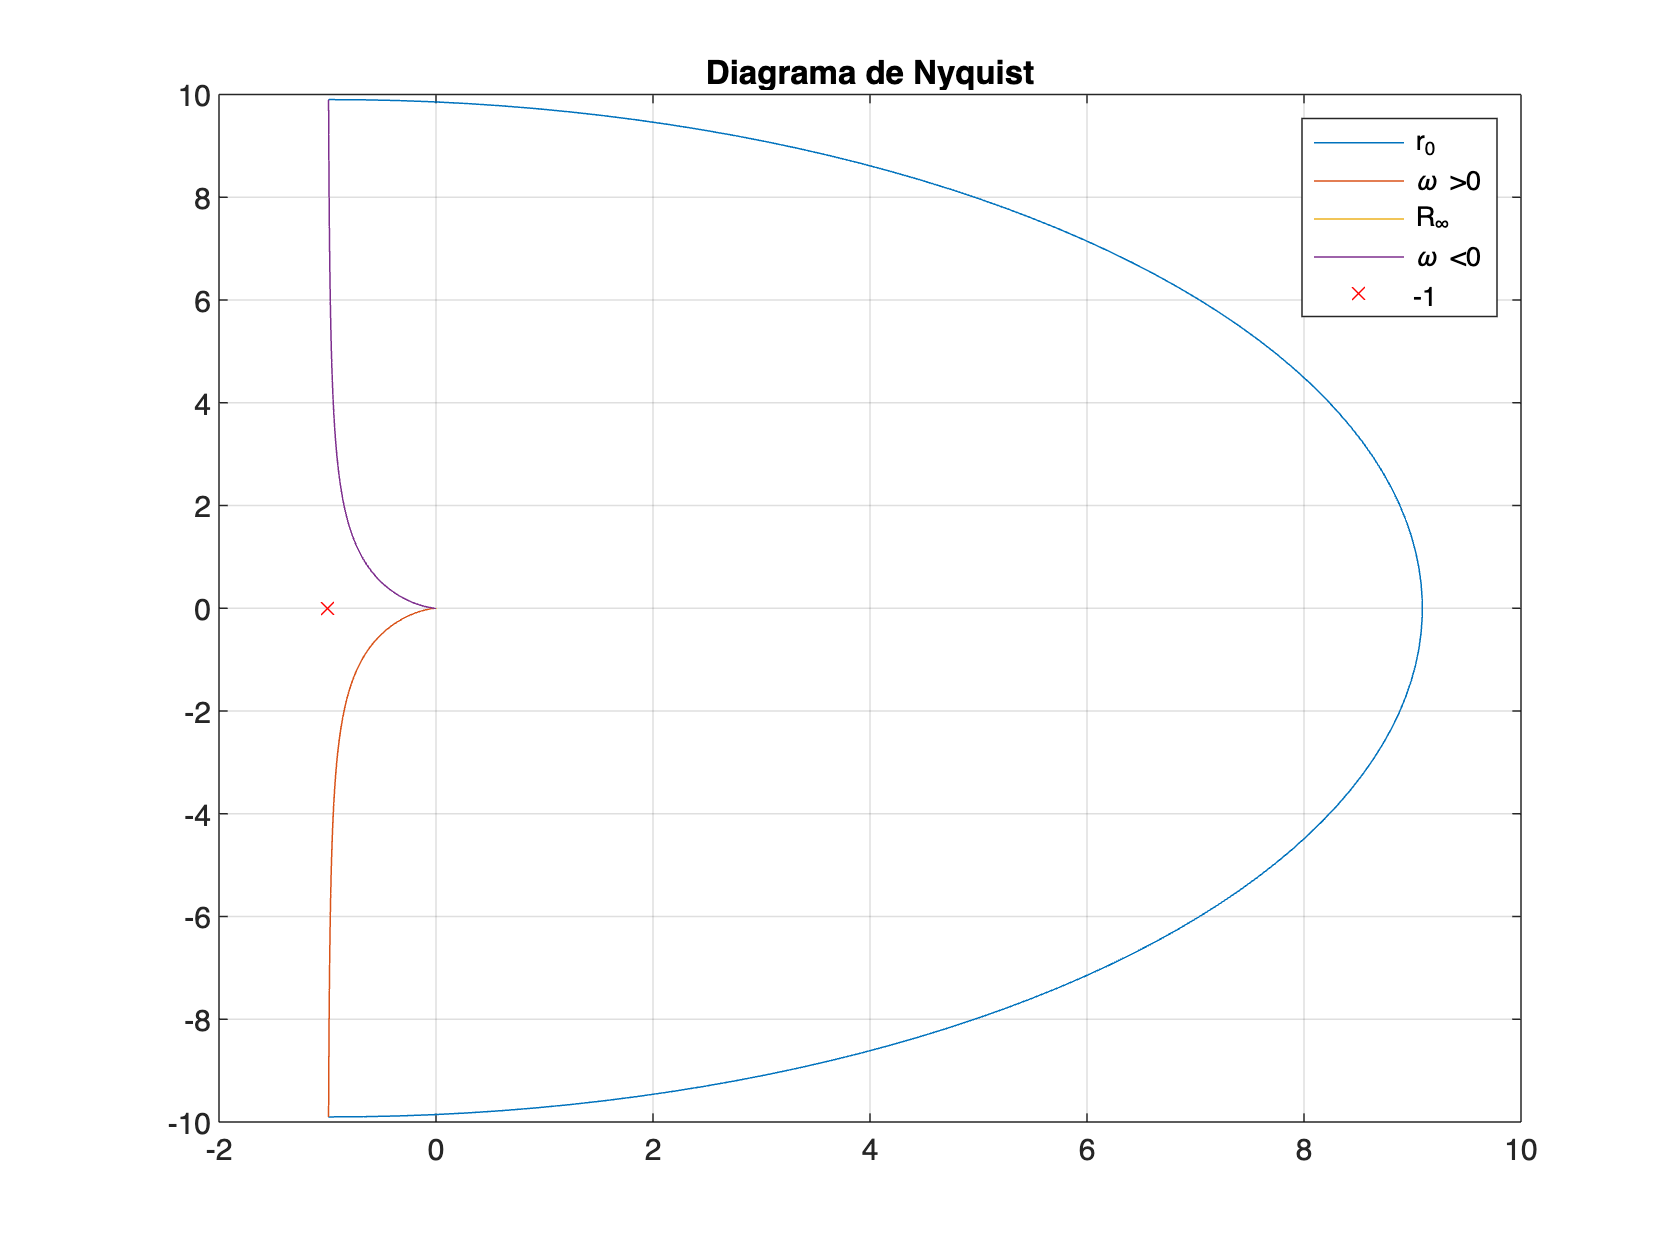

Nmax = 2;
Nmin = -1;
w_vec = logspace(Nmin,Nmax,100);
R = 10^Nmax;
theta_vec = linspace(pi/2,-pi/2,100);
Rpequeno = 10^Nmin;
s0 = Rpequeno*flip(exp(1i*theta_vec));
s1 = 1i*w_vec;
s2 = R*exp(1i*theta_vec);

% sistema com polo na origem:
G = @(s) 1./s./(s+1);
figure();

plot(G([s0]));hold all;plot(G([s1])); title('Diagrama de Nyquist')
plot(G(s2)); plot(G(-flip(s1))); 
plot([-1+0.00000000001i], 'xr'); %axis([-1.5 1.5 -1 1])
legend('r_0', '\omega >0', 'R_\infty', '\omega <0', '-1'); grid on;

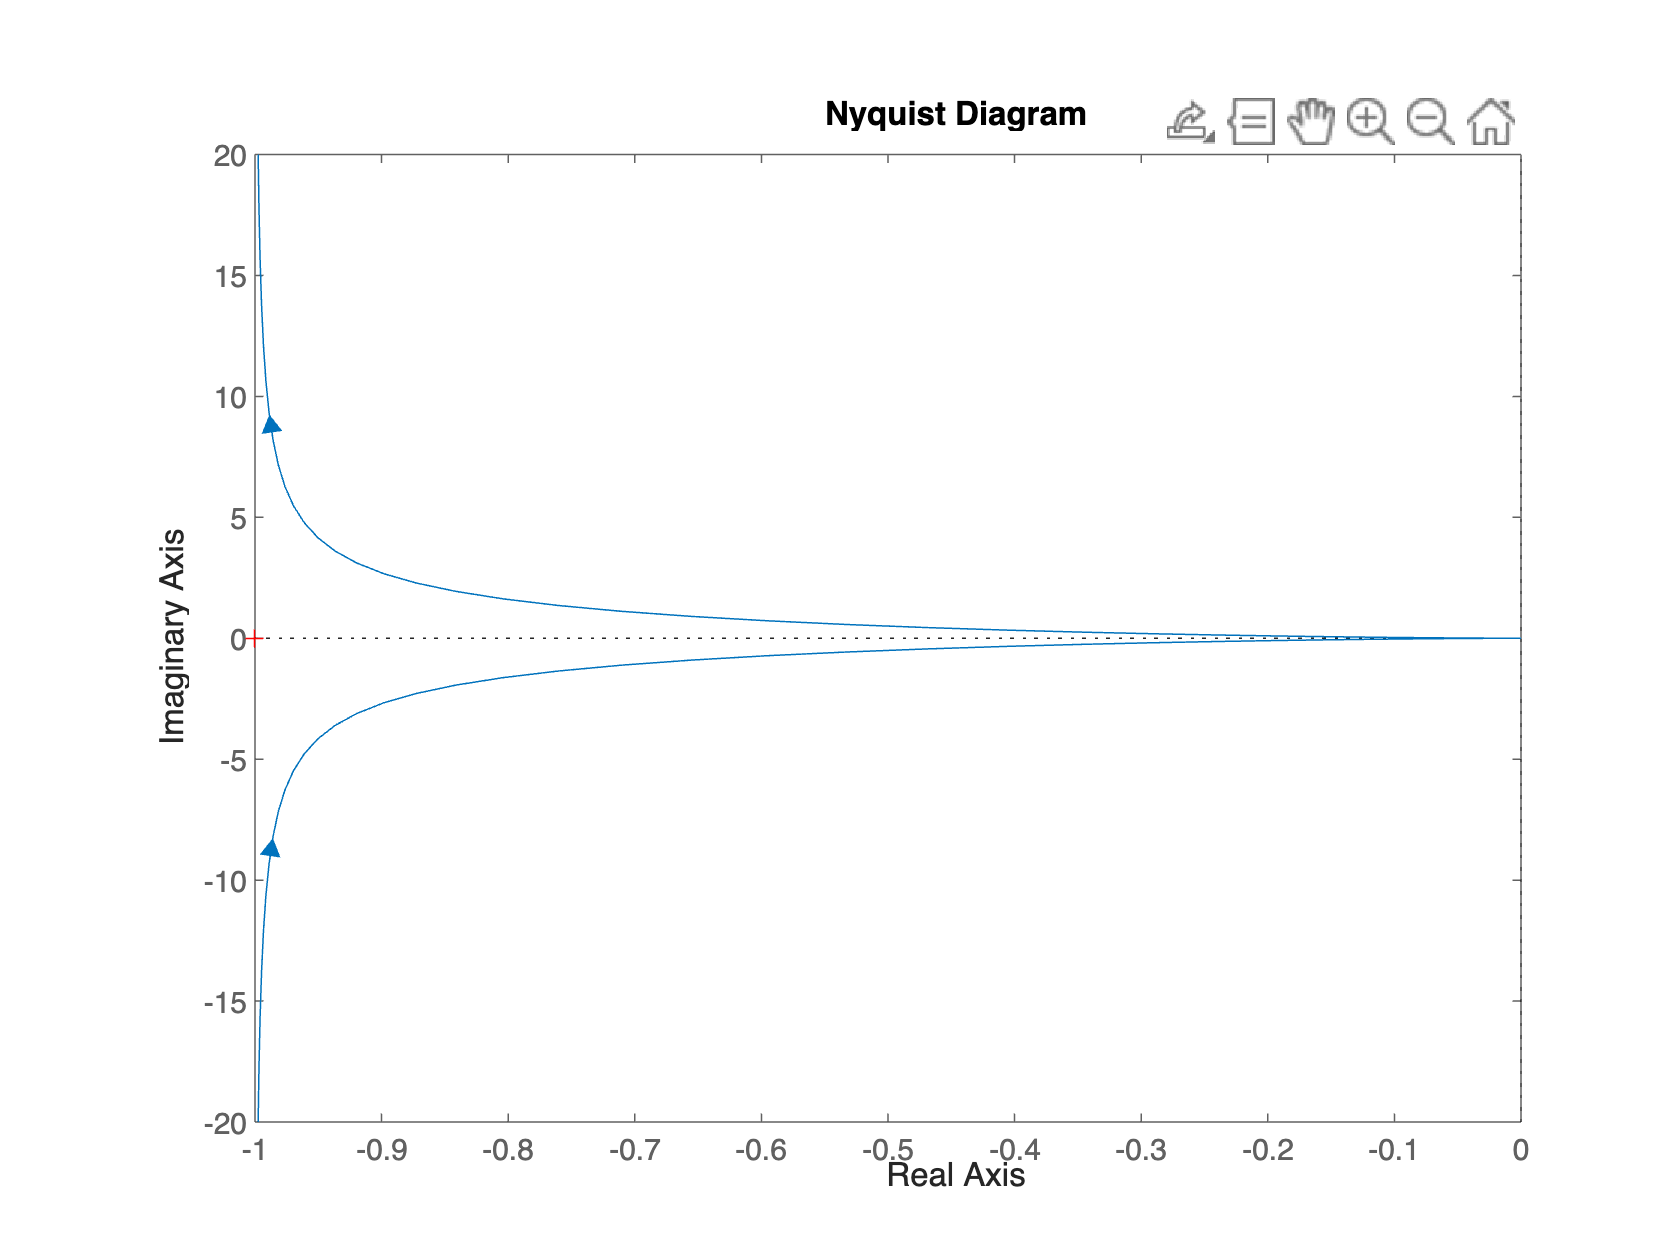

%%
s = tf('s');
L = 1/(s*(s+1));
figure;
nyquist(L)